Digital filter specifications


% Read the .wav file
[x, fs] = audioread("Goutami.wav");
%Barlett
Sampling_frequency = fs

Sampling_frequency = 44100

Transition_band = 900

Transition_band = 900

Fp = 3 * 10^3

Fp = 3000

Ks = 25

Ks = 25

Fs = 3.9 * 10^3

Fs = 3900

Sampling_time = 1 / Sampling_frequency

Sampling_time = 2.2676e-05

Omega_p = 2 * pi * Fp

Omega_p = 1.8850e+04

Omega_s = 2 * pi * (Fp + Transition_band)

Omega_s = 2.4504e+04


%% Converting the analog filter specifications into digital specifications
% Using the formula, w = Omega * Sampling_Time
Wp = Omega_p * Sampling_time

Wp = 0.4274

Ws = Omega_s * Sampling_time

Ws = 0.5557


% Select the appropriate window to meet the requirement
% Order of the filter
k = 4 % k value for Hamming, Hanning, and Bartlett window

k = 4

N = (8 * pi) / (Ws - Wp);
N = ceil(N) % To get the alpha as an integer

N = 196

if (mod(N,2)==0)
  Alpha = N / 2
else
  Alpha = (N - 1) / 2
end

Alpha = 98


%% Cutoff frequency
Wc2 = Wp + ((Ws - Wp) / 2);
Wc1=300*2*pi/44100

Wc1 = 0.0427

%% The impulse response of the desired lowpass filter using the Barlett window
p = 0:N-1

p =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


for n = 1:N
    if n <= (N+1)/2
        WHam(n) = (2 / (N - 1)) * (n - 1);
    else
        WHam(n) = 2 - (2 / (N - 1)) * (n - 1);
    end
end
WHam

WHam =          0    0.0103    0.0205    0.0308    0.0410    0.0513    0.0615    0.0718    0.0821    0.0923    0.1026    0.1128    0.1231    0.1333    0.1436    0.1538    0.1641    0.1744    0.1846    0.1949    0.2051    0.2154    0.2256    0.2359    0.2462    0.2564    0.2667    0.2769    0.2872    0.2974    0.3077    0.3179    0.3282    0.3385    0.3487    0.3590    0.3692    0.3795    0.3897    0.4000    0.4103    0.4205    0.4308    0.4410    0.4513    0.4615    0.4718    0.4821    0.4923    0.5026


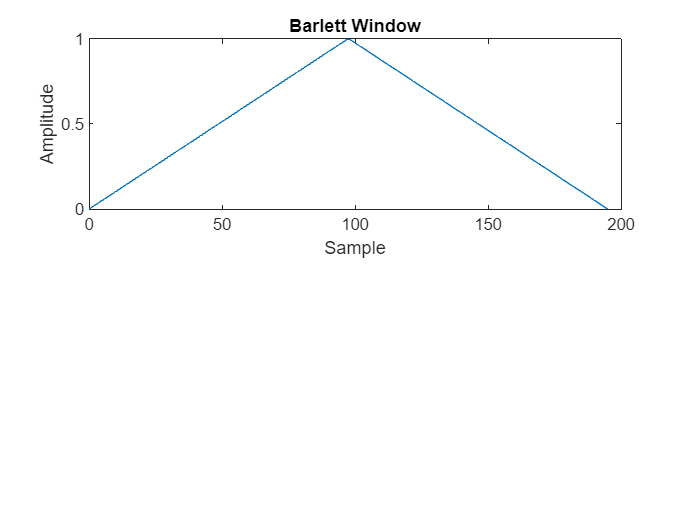

%% The impulse response of the FIR lowpass filter
h = ideal_bp_filter(Wc1, Wc2, N) .* WHam; % Convolution with Barlett window

figure;
subplot(2,1,1);
plot(p,  WHam);
title('Barlett Window');
xlabel('Sample');
ylabel('Amplitude');

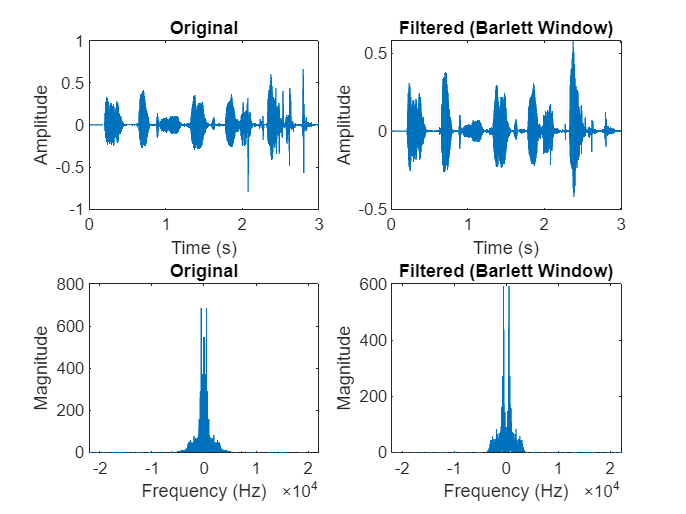


res = conv(x, h);
subplot(2,2,1);
t = (0:length(x)-1) / fs;
plot(t, x);
title('Original');
xlabel('Time (s)');
ylabel('Amplitude');
t = (0:length(res)-1) / Sampling_frequency; % Time vector

subplot(2,2,2);
plot(t, res);
title('Filtered (Barlett Window)');
xlabel('Time (s)');
ylabel('Amplitude');

n = length(x);  % Set n based on the length of the signal
y = fft(x, n);
m = abs(y);
f = (0:length(y)-1) * fs / length(y);
Y = fftshift(m);
fshift = (-n/2:n/2-1) * (fs/n);

% Filtered
nf = length(res);  % Set n based on the length of the signal
yf = fft(res, nf);
mf = abs(yf);
ff = (0:length(yf)-1) * Sampling_frequency / length(yf);
Yf = fftshift(mf);
fshiftf = (-nf/2:nf/2-1) * (Sampling_frequency/nf);

subplot(2,2,3);
plot(fshift, Y);
title('Original');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(2,2,4);
plot(fshiftf, Yf);
title('Filtered (Barlett Window)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

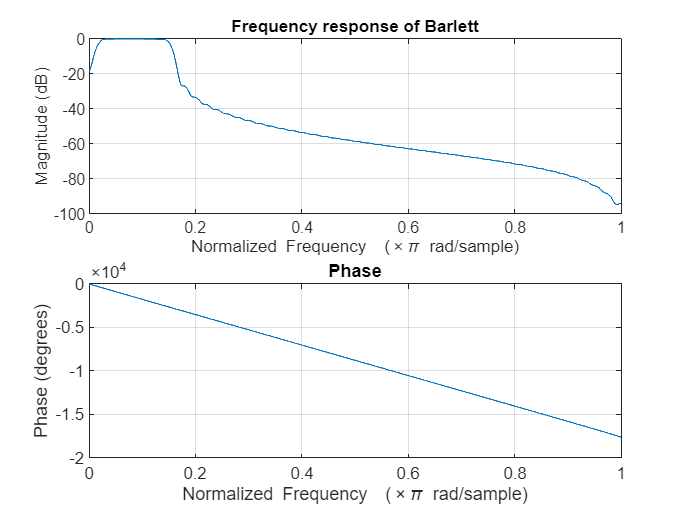


% Ideal BAndpass filter function
figure
freqz(h, 1, Sampling_frequency);
title('Frequency response of Barlett');

function hd = ideal_bp_filter(wc1, wc2, N)
    % Ideal bandpass filter function
    % wc1: Lower cutoff frequency
    % wc2: Upper cutoff frequency
    % N: Filter order
    n = 0:N-1;
    hd = (wc2 / pi) * sinc(wc2 * (n - (N / 2)) / pi) - (wc1 / pi) * sinc(wc1 * (n - (N / 2)) / pi);
end

